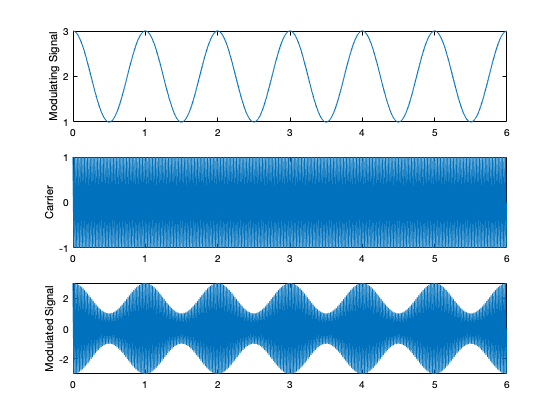

%Amplitude modulation 
%AM.mlx
clear all; 
close all;
f0= 1; %Fundamental Freq. (Natural Freq.)
P= 6; %Period of signal
%objSinusoid; %call function to generate all sinusoid waveforms
T= 0.005; % Time spacing
fs= 1/T; %Sampling freq.
t= (0:T:(P-T)); %Time axis, vector
N= length(t); % length of signal waveform 
fm= 1; %Message Freq.   
fc= 50; %Carrier Freq.
crr= cos(2*pi*fc*f0*t);  
anlgDat= cos(2*pi*fm*f0*t)+ 2; 
%am=(1/2)*(cos(2*pi*(fc+fm)*f0*t)+cos(2*pi*(fc-fm)*f0*t));
%am=(1/2)*(cos(2*pi*(fc+fm)*f0*t)+cos(2*pi*(fc-fm)*f0*t)) + 2*crr;
am= crr.*anlgDat; % dot product multiplication (because we want the same output length)
figure; subplot(311);plot(t,anlgDat); ylabel('Modulating Signal'); % Message
subplot(312);plot(t,crr); ylabel('Carrier');
subplot(313);plot(t,am); ylabel('Modulated Signal');

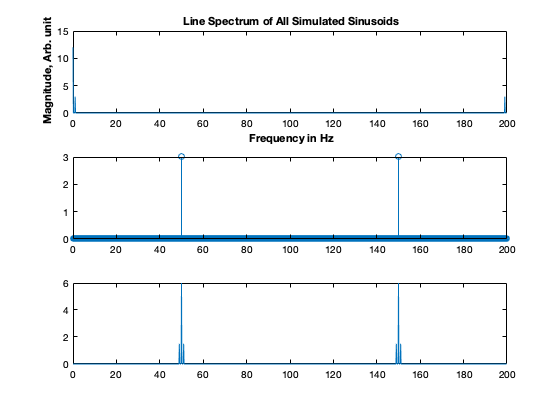


%Line Spectrum Estimation
sigAll= [anlgDat; crr; am]; % matrix of message, carrier, ampMod
[fd, f, mag]= doubSpec(sigAll,T); %call doubleSpectrum function from `doubSpec.m` file
figure; subplot(311); plot(f, mag(1,:)); % mag(1) = message
title('\bf Line Spectrum of All Simulated Sinusoids');
xlabel('\bf Frequency in Hz'); ylabel('\bf Magnitude, Arb. unit');
subplot(312); stem(f, mag(2,:)); % mag(2) = carrier
subplot(313); plot(f, mag(3,:)); % mag(3) = ampMod

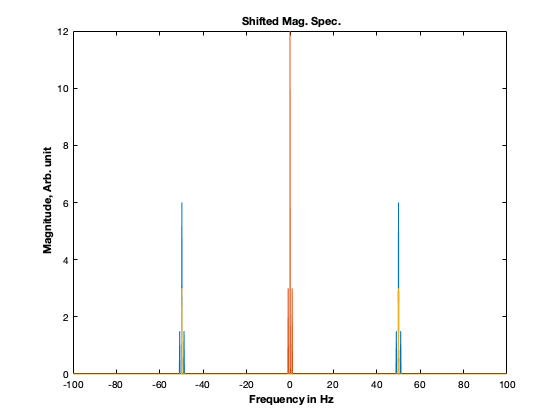

mgdbShft= fftshift(mag); % Shifting  Spectrum around freq. axis
fsR= (0:fd:(N/2-1)*fd);
fsL= ((-(N/2-1):1:0)*fd);
fdbShft= [fsL fsR]; % freq axis for shifted spectrum 
figure,plot(fdbShft,mgdbShft); % shift scale to -50 Hz to 50 Hz 
title('\bf Shifted Mag. Spec.');
xlabel('\bf Frequency in Hz'); ylabel('\bf Magnitude, Arb. unit');